clear all
close all
clc

%%
% set tuid and amplitude
tuid = [9,1,6,0,2,7,2,0,7];
A = tuid(9) + 2; % amplitude [Volts]
rb = 1000 * (tuid(8) + 3);      % Bit rate hz

Tb = 1/rb;          % bit interval     

fs = 100*rb;        % Sampling rate
Ts = 1/fs;          % Sampling Interval

M = 2;              % Numbe of symbols
N = 30;             % Number of bits to be transmitted

Ns = floor(Tb/Ts);  % Number of samples per bit

## Polar Non-Return to Zero

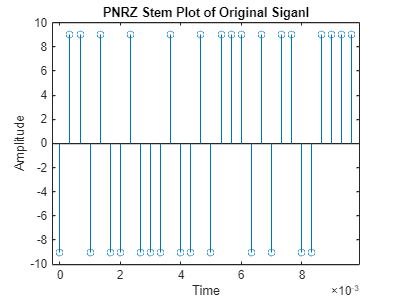

[t1,pnrz,t2,signal_prnz] = polar_nrz(A,rb,fs,N); % Polar Non return to zero scheme


figure(1)
stem(t1,pnrz);
xlabel('Time')
ylabel('Amplitude')
title('PNRZ Stem Plot of Original Siganl')
saveas(1,'PNRZ_STEM.jpg')

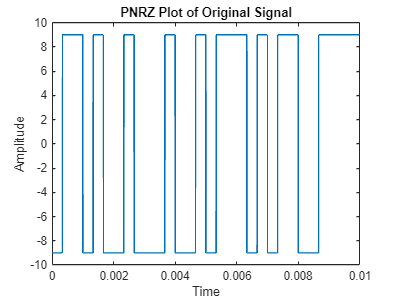


figure(2)
plot(t2,signal_prnz)
xlabel('Time')
ylabel('Amplitude')
title('PNRZ Plot of Original Signal')
saveas(2,'PNRZ_SIG.jpg')

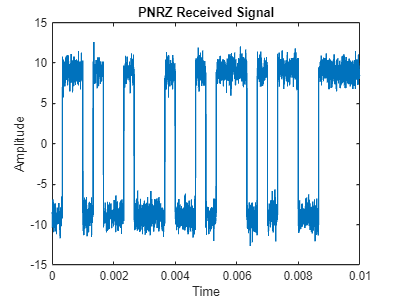


received = awgn(signal_prnz,0); % Passing the signal through a noisy channel

%% Matched filtering 
filtered_signal = zeros(1,N);

pulse = ones(1,Ns); % Reference pulse
pulse = pulse.*(A);

% Performing matched filtering
for i = 1:length(signal_prnz)/Ns
    idx = (i-1)*Ns+1:(i-1)*Ns+Ns;
    filtered = conv(received(idx),pulse);
    filtered_signal(i) =  filtered(Ns);
end
filtered_signal = filtered_signal/(A^2*Ns);
%% Detection 
detected = filtered_signal;
detected(filtered_signal>=0.5)=1;
detected(filtered_signal<0.5)=-1;

figure(3)
plot(t2,received)
xlabel('Time')
ylabel('Amplitude')
title('PNRZ Received Signal')
saveas(3,'PNRZ_REC.jpg')

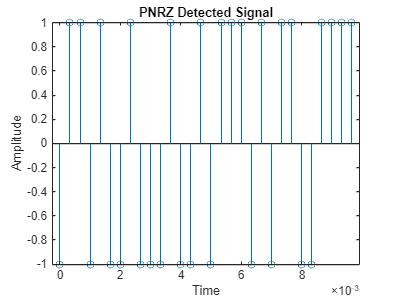


figure(4)
stem(t1,detected);
xlabel('Time')
ylabel('Amplitude')
title('PNRZ Detected Signal')
saveas(4,'PNRZ_DET.jpg')

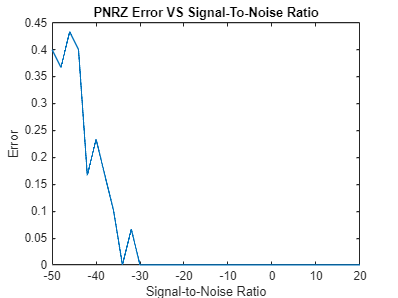


my_range = -50:2:20;
results = zeros(size(my_range));
for index=1:length(my_range)
    results(index) = pnrz_calc_error(my_range(index),signal_prnz,N,Ns,A,t1,pnrz);
end

figure(5)
plot(my_range, results)
ylabel('Error')
xlabel('Signal-to-Noise Ratio')
xlim([min(my_range), max(my_range)])
title('PNRZ Error VS Signal-To-Noise Ratio')
saveas(5,'PNRZ_ERROR.jpg')

## Unipolar Non-Return to Zero

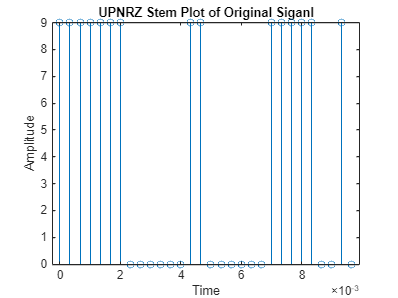

[t1,upnrz,t2,signal_uprnz] = unipolar_nrz(A,rb,fs,N); % Polar Non return to zero scheme


figure(6)
stem(t1,upnrz);
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ Stem Plot of Original Siganl')
saveas(6,'UPNRZ_STEM.jpg')

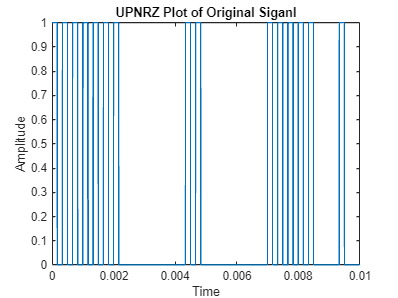


figure(7)
plot(t2,signal_uprnz)
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ Plot of Original Siganl')
saveas(7,'UPNRZ_SIG.jpg')

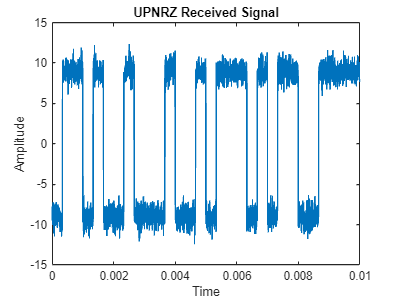


received1 = awgn(signal_prnz,0); % Passing the signal through a noisy channel

%% Matched filtering 
filtered_signal1 = zeros(1,N);

pulse = ones(1,Ns); % Reference pulse
pulse = pulse.*(A);

% Performing matched filtering
for i = 1:length(signal_uprnz)/Ns
    idx = (i-1)*Ns+1:(i-1)*Ns+Ns;
    filtered1 = conv(received(idx),pulse);
    filtered_signal1(i) =  filtered(Ns);
end
filtered_signal1 = filtered_signal1/(A^2*Ns);
%% Detection 
detected = filtered_signal1;
detected1(filtered_signal1>=0.5)=1;
detected1(filtered_signal1<0.5)=-1;

figure(8)
plot(t2,received1)
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ Received Signal')
saveas(8,'UPNRZ_REC.jpg')

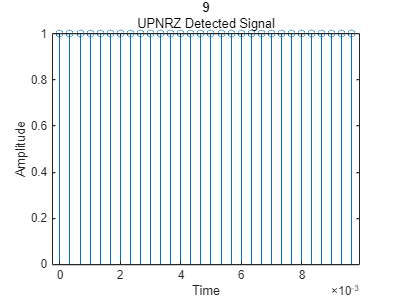


figure(9)
stem(t1,detected1);
xlabel('Time')
ylabel('Amplitude')
title(9,'UPNRZ Detected Signal')
saveas(9,'UPNRZ_DET.jpg')

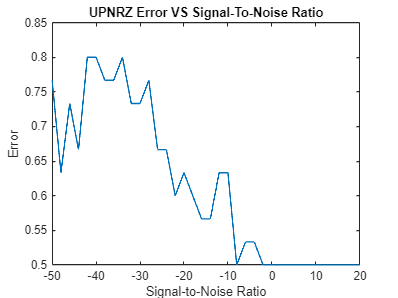


my_range = -50:2:20;
results1 = zeros(size(my_range));
for index=1:length(my_range)
    results1(index) = upnrz_calc_error(my_range(index),signal_uprnz,N,Ns,A,t1,upnrz);
end

figure(10)
plot(my_range, results1)
ylabel('Error')
xlabel('Signal-to-Noise Ratio')
xlim([min(my_range), max(my_range)])
title('UPNRZ Error VS Signal-To-Noise Ratio')
saveas(10,'UPNRZ_ERROR.jpg')

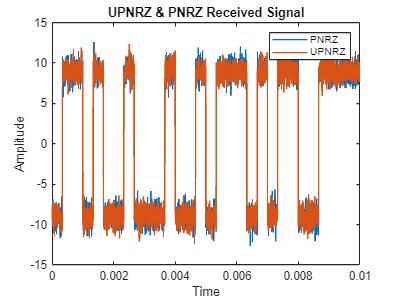


figure(11)
plot(t2,received)
hold on
plot(t2,received1)
xlabel('Time')
ylabel('Amplitude')
legend('PNRZ','UPNRZ')
title('UPNRZ & PNRZ Received Signal')
saveas(11,'DUAL_REC.jpg')

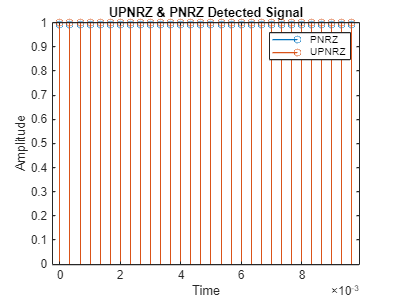


figure(12)
stem(t1,detected);
hold on
stem(t1,detected1);
legend('PNRZ','UPNRZ')
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ & PNRZ Detected Signal')
saveas(12,'DUAL_DET.jpg')

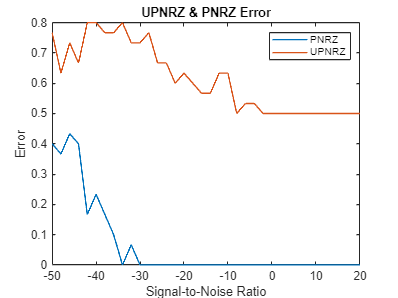


figure(13)
plot(my_range, results)
hold on
plot(my_range, results1)
legend('PNRZ','UPNRZ')
ylabel('Error')
xlabel('Signal-to-Noise Ratio')
xlim([min(my_range), max(my_range)])
title('UPNRZ & PNRZ Error')
saveas(13,'DUAL_ERROR.jpg')

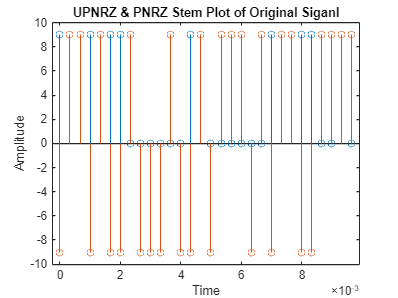


figure(14)
stem(t1,upnrz);
hold on
stem(t1,pnrz);
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ & PNRZ Stem Plot of Original Siganl')
saveas(14,'DUAL_STEM.jpg')

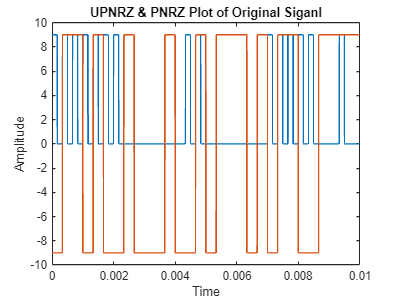


figure(15)
plot(t2,A.*signal_uprnz)
hold on
plot(t2,signal_prnz)
xlabel('Time')
ylabel('Amplitude')
title('UPNRZ & PNRZ Plot of Original Siganl')
saveas(15,'DUAL_SIG.jpg')

## Function

function [error] = pnrz_calc_error(snr_db, signal_prnz, N, Ns,A,t1,pnrz)

%% Noisy Channel

received = awgn(signal_prnz,snr_db); % Passing the signal through a noisy channel

%% Matched filtering 
filtered_signal = zeros(1,N);

pulse = ones(1,Ns); % Reference pulse
pulse = pulse.*(A);

% Performing matched filtering
for i = 1:length(signal_prnz)/Ns
    idx = (i-1)*Ns+1:(i-1)*Ns+Ns;
    filtered = conv(received(idx),pulse);
    filtered_signal(i) =  filtered(Ns);
end
filtered_signal = filtered_signal/(A^2*Ns);
%% Detection 
detected = filtered_signal;
detected(filtered_signal>=0)=1;
detected(filtered_signal<0)=-1;


%% Performance 
error = sum(detected~=pnrz/A)/N;

end


## Function

function [error] = upnrz_calc_error(snr_db, signal_prnz, N, Ns,A,t1,pnrz)

%% Noisy Channel

received = awgn(signal_prnz,snr_db); % Passing the signal through a noisy channel

%% Matched filtering 
filtered_signal = zeros(1,N);

pulse = ones(1,Ns); % Reference pulse
pulse = pulse.*(A);

% Performing matched filtering
for i = 1:length(signal_prnz)/Ns
    idx = (i-1)*Ns+1:(i-1)*Ns+Ns;
    filtered = conv(received(idx),pulse);
    filtered_signal(i) =  filtered(Ns);
end
filtered_signal = filtered_signal/(A^2*Ns);
%% Detection 
detected = filtered_signal;
detected(filtered_signal>=0)=1;
detected(filtered_signal<0)=-1;


%% Performance 
error = sum(detected~=pnrz/A)/N;

end

